The kernel super class allows addition subtraction multiplication and division.

A kernel can then be made periodic in a given dimension or set of dimensions with an enforced period.

A kernel matrix can then be constructed using the build method of a kernel.

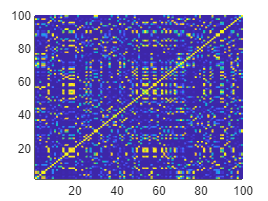

clear all
close all
clc

xx = lhsdesign(100,1);

a = kernels.EQ(3,1).periodic(1,0.3);

b = kernels.Matern52(2,0.1).periodic(1,0.6);

c = kernels.RQ(0.5,0.1);

[K, dK] = b.build(xx,xx);

figure
pcolor(K)
shading flat

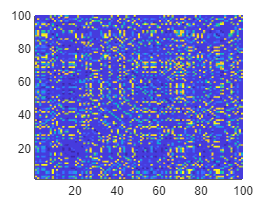

figure
pcolor(dK(:,:,1))
shading flat

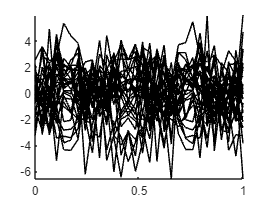

Z = GP([],b);
x1 = linspace(0,1,30)';

figure
hold on
for i = 1:30
    ysamp = Z.samplePrior(x1);
    plot(x1,ysamp,'LineWidth',0.05,'Color','k')
end